# Mètode del punt fix o Mètode de la iteració simple

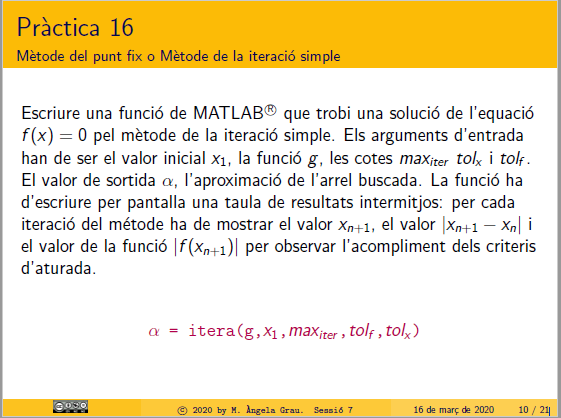  

format long G
g = @(x)cos(x); x1 = 1; maxiter = 15; tolf = 0.5*10^(-18); tolx = 0.5*10^(-18);
f = @(x)cos(x) -x;
dg = @(x)-sin(x);
alpha = itera(f, g, dg, x1, maxiter, tolf, tolx)

T1 = 15×4 table
    k            x_n                  tolf                   tolx        
    __    _________________    ___________________    ___________________

     0                    1                    Inf                    Inf
     1     0.54030230586814      0.317250909978254       0.45969769413186
     2    0.857553215846393      0.203263425348614      0.317250909978254
     3    0.654289790497779      0.139190568244786      0.203263425348614
     4    0.793480358742566     0.0921115851198091      0.139190568244786
     5    0.701368773622757     0.0625909092778977     0.0921115851198091
     6    0.763959682900654     0.0418572578739465     0.0625909092778977
     7    0.722102425026708     0.0283153367370528     0.0418572578739465
     8    0.750417761763761     0.0190137193412507     0.0283153367370528
     9     0.73140404242251     0

alpha =          0.740147335567876


alpha = fzero(f,x1)

alpha =          0.739085133215161


x0=0.5; 
f =@(x)x+log(x);
g=@(x)exp(-x); 
dg=@(x)-exp(-x);
tol=0.0005; nmax=15;
alpha = itera( f, g, dg, x0, nmax, tol, tol)

T1 = 11×4 table
    k            x_n                   tolf                    tolx        
    __    _________________    ____________________    ____________________

     0                  0.5                     Inf                     Inf
     1    0.606530659712633       0.106530659712633       0.106530659712633
     2    0.545239211892605      0.0612914478200284      0.0612914478200284
     3    0.579703094878068      0.0344638829854633      0.0344638829854632
     4    0.560064627938902      0.0196384669391663      0.0196384669391664
     5    0.571172148977215      0.0111075210383133      0.0111075210383133
     6    0.564862946980323     0.00630920199689167     0.00630920199689167
     7    0.568438047570066     0.00357510058974275     0.00357510058974275
     8    0.566409452746921     0.00202859482314555     0.00202859482314544
     9    0

alpha =          0.566907212935471


# Convergència "a priori"               

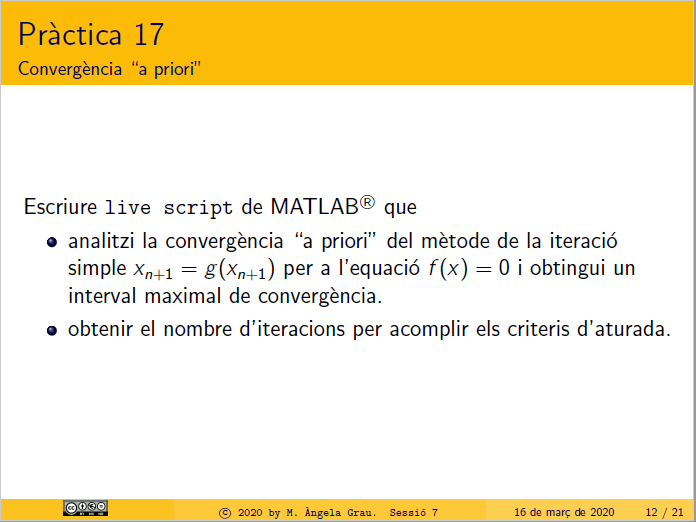

# Convergència "a priori"

t = 0.01:0.01:1;
f=@(x)x+log(x);
y=zeros(size(t));
subplot(221),plot(t,f(t),t,y),title('x+log(x)=0');
dg = @(x)-1./x;
subplot(222),convergencia_a_priori(dg,t);

dgt =                       -100                       -50         -33.3333333333333                       -25                       -20         -16.6666666666667         -14.2857142857143                     -12.5         -11.1111111111111                       -10         -9.09090909090909         -8.33333333333333         -7.69230769230769         -7.14285714285714         -6.66666666666667                     -6.25         -5.88235294117647         -5.55555555555555         -5.26315789473684                        -5         -4.76190476190476         -4.54545454545455         -4.34782608695652         -4.16666666666667                        -4         -3.84615384615385          -3.7037037037037         -3.57142857142857         -3.44827586206897         -3.33333333333333          -3.2258064516129                    -3.125         -3.03030303030303         -2.94117647058824         -2.85714285714286         -2.77777777777778          -2.7027027027027         -2.63157894736842      

dg=@(x)-exp(-x);
subplot(223),convergencia_a_priori(dg,t);

dgt =         -0.990049833749168        -0.980198673306755        -0.970445533548508        -0.960789439152323        -0.951229424500714        -0.941764533584249        -0.932393819905948        -0.923116346386636        -0.913931185271228         -0.90483741803596        -0.895834135296528        -0.886920436717157        -0.878095430920561        -0.869358235398806        -0.860707976425058        -0.852143788966211        -0.843664816596384        -0.835270211411272        -0.826959133943362        -0.818730753077982        -0.810584245970187        -0.802518797962478        -0.794533602503334        -0.786627861066553        -0.778800783071405        -0.771051585803566        -0.763379494336853        -0.755783741455725        -0.748263567578565        -0.740818220681718        -0.733446956224289        -0.726149037073691        -0.718923733431926         -0.71177032276261        -0.704688089718713        -0.697676326071031        -0.690734330637355        -0.683861409212356      

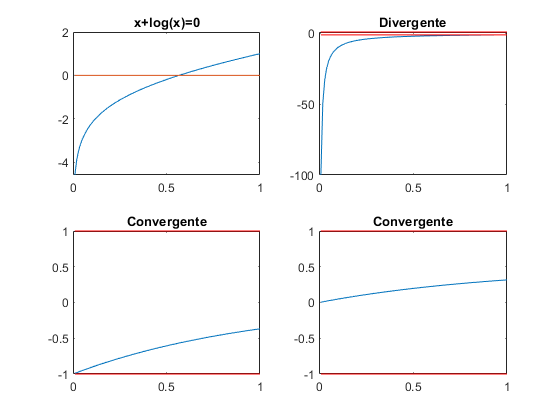

dgt =        0.00497508312541595       0.00990066334662237        0.0147772332257459        0.0196052804238384         0.024385287749643        0.0291177332078756        0.0338030900470259        0.0384418268066821        0.0430344073643859        0.0475812909820202        0.0520829323517359        0.0565397816414213        0.0609522845397193        0.0653208823005971        0.0696460117874711        0.0739281055168943        0.0781675917018081         0.082364894294364        0.0865204330283189        0.0906346234610091        0.0947078770149065        0.0987406010187608         0.102733198748333         0.106686069466723         0.110599608464298         0.114474207098217         0.118310252831573         0.122108129272137         0.125868216210717         0.129590889659141         0.133276521887855         0.136925481463155         0.140538133284037         0.144114838618695         0.147655955140643         0.151161836964484         0.154632834681323         0.158069295393822      

dg=@(x)(1-exp(-x))/2;
subplot(224),convergencia_a_priori(dg,t);

# Nombre d'iteracion 

**Obtenir el nombre d'iteracions per acomplir els criteris d'aturada**

x0=0.5; 
f =@(x)x+log(x);
g=@(x)exp(-x); 
dg=@(x)-exp(-x);
tol=eps; nmax=15;
if abs(dg(x0))<1
    alpha = itera( f, g, x0, Inf, eps, eps)
else
    fprintf('\n Mètode divergent\n')
end

T1 = 61×4 table
    k            x_n                   tolf                    tolx        
    __    _________________    ____________________    ____________________

     0                  0.5                     Inf                     Inf
     1    0.606530659712633       0.106530659712633       0.106530659712633
     2    0.545239211892605      0.0612914478200284      0.0612914478200284
     3    0.579703094878068      0.0344638829854633      0.0344638829854632
     4    0.560064627938902      0.0196384669391663      0.0196384669391664
     5    0.571172148977215      0.0111075210383133      0.0111075210383133
     6    0.564862946980323     0.00630920199689167     0.00630920199689167
     7    0.568438047570066     0.00357510058974275     0.00357510058974275
     8    0.566409452746921     0.00202859482314555     0.00202859482314544
     9    0

alpha =          0.567143290409784


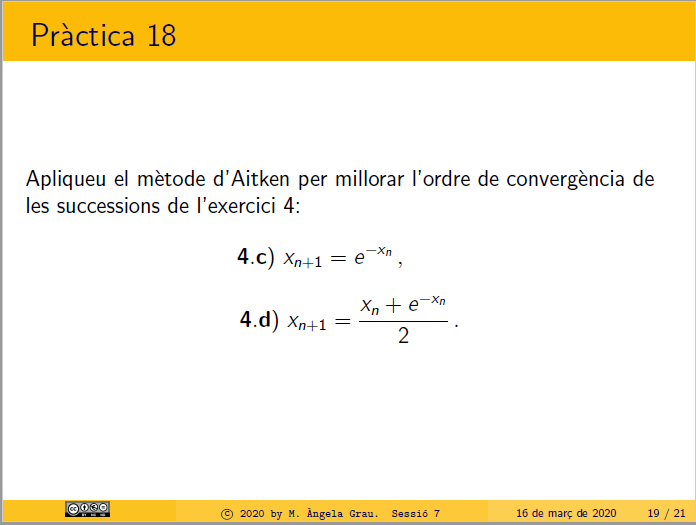

# Mètode d'Aitken

4c)

f =@(x)x+log(x);
g=@(x)exp(-x); 
dg=@(x)-exp(-x);
x0=0.5; tol = 0.000002;
maxiter = 9;
[A] = aitkenfixpt(f, g, dg, x0, maxiter, tol)

A =           0.56762387641092
          0.56714331410558
         0.567143290706341
           0.5671433262075
         0.567143290508074
         0.567143266471691
         0.567143290248554
         0.567143267700805
         0.567143290917171


4d)

f =@(x)x+log(x);
g = @(x) ((x+exp(-x))/2);
dg = @(x) ((1-exp(-x))/2);
tol = 0.000002;
x0 = 0.5;
maxiter = 9;
[A] = aitkenfixpt(f, g, dg, x0, maxiter, tol)

A =          0.566972608196341
         0.567143289268964
         0.567143288722299
         0.567143314236141
         0.567143290268502
         0.567143118601463
         0.567143290520296
         0.567143189062183
          0.56714329066611


# Mètode del punt fix o Mètode de la iteració simple

function [xn] = itera(f, g, dg, x1, maxiter, tolf, tolx)
    if abs(dg(x1))<1
        xnmas1 = x1;
        xn = x1;
        k = 0;
        R  = [k,x1,Inf,Inf];
        cotaf=Inf; 
        cotax=Inf;
        while(abs(cotaf) >tolf &&  abs(cotax) > tolx && k< maxiter)
            xn = xnmas1;
            xnmas1 = g(xnmas1);
            k = k+1;
            cotaf = abs(f(xnmas1));
            cotax = abs(xnmas1-xn);
            R  = [R ;k xnmas1 cotaf cotax];
        end
        R = R(1:(end-1),:);
        T1 = array2table(R,'VariableNames',{'k','x_n','tolf','tolx'})
    else 
        fprintf('\n Mètode divergent\n')
    end
end

# Convergència "a priori"

function convergencia_a_priori(dg,t)
    y=ones(size(t));
    plot(t,dg(t),t,y,'r',t,-y,'r');
    dgt = dg(t)
    %si -1<=dgt<= 1 convergente sino divergente
    dgt(dgt>1) = 2;
    dgt(dgt<-1) = 2;
    if ismember(2,dgt)
        title('Divergente')
    else
        title('Convergente')
    end
end

# mètode d'Aitken

function [A] = aitkenfixpt(f, g, dg, x0, maxiter, tol)
        A = [];
        if abs(dg(x0)) < 1
            %Metode d'Aitken
            i = 0;
            while (i < maxiter && abs(x0) > tol)
                x1 = g(x0);
                x2 = g(x1);
                aitkenX = (x2*x0-x1^2)/(x2-2*x1+x0);
                A = [A; aitkenX];
                x0 = aitkenX;
                i = i+1;
            end
        else
            fprintf('Mètode divergent\n')
        end
end